## [Classification with Machine Learning](https://apmonitor.com/pds/index.php/Main/ClassificationOverview)

Classification is the problem of identifying which set of categories based on observation features. The decision is based on a training set of data containing observations where category membership is known (supervised learning) or where category membership is unknown (unsupervised learning).

A basic example is to determine the number from pixelated images in a built-in sklearn dataset. The script predicts 0-9 from the following images with a Support Vector Classifier.

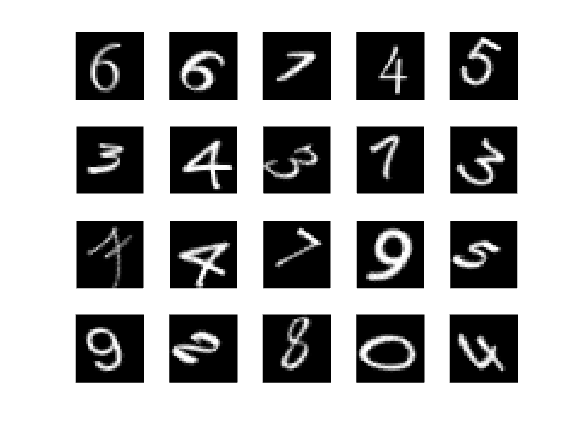

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

n_samples = length(imds.Files)

n_samples = 10000


% data = reshape(readimage(imds,1)',[1,28*28]);

X_data = [];
for i = 1:n_samples
    X_data = [X_data; reshape(readimage(imds,i)',[1,28*28])];
end

Y_data = imds.Labels(1:n_samples);


% Fix code to randomize these
X_Train = X_data(1:n_samples/2,:);
X_Test = X_data(n_samples/2+1:n_samples,:);
Y_Train = Y_data(1:n_samples/2,:);
Y_Test = Y_data(n_samples/2+1:n_samples,:);


classifier = fitcecoc(array2table(im2double(X_Train)),Y_Train);
ypred = predict(classifier,array2table(im2double(X_Test)));

ypred = 5000×1 categorical array
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     0 
     0 
     3 
     3 
     3 
     0 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     2 
     3 
     3 
     3 
     3 


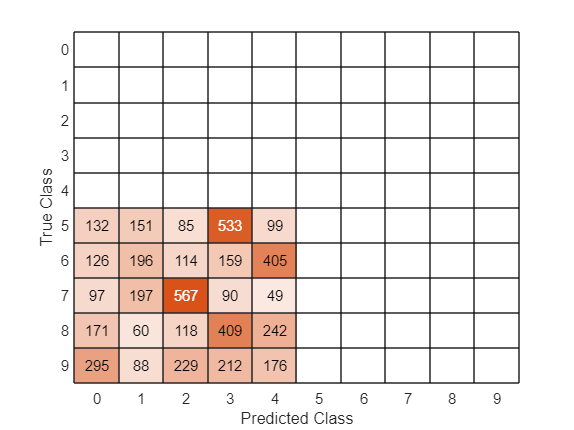


figure;
confusionchart(Y_Test,ypred)

% numTrainFiles = 750;
% [imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomized');
% X_train = imdsTrain.Files
% y_train = imdsTrain.Labels
% 
% fitcsvm(X_train,y_train)